Visualize kinetic functions

clc
clearvars

volt = -70:70;

% default kinetic parameter
kto_default = [33, 15.5, 20, 7, 0.03577, 0.06237, 0.18064, 0.3956, 0.000152, 0.067083, 0.00095, 0.051335];
kslow1_default = [22.5, 45.2, 40.0, 7.7, 5.7, 0.0629, 6.1, 18.0, 2.058, 803.0];
kslow2_default = [4912, 5334];
kss_default = [0.0862, 1235.5, 13.17, kslow1_default(3)];

IKto

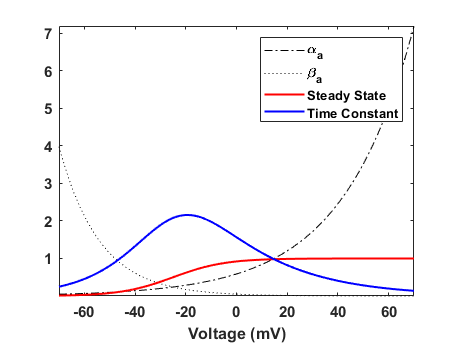

kto_kv = ikto_kinetic_var(kto_default,volt);

figure('Color','w')
plot(volt,kto_kv(:,1), '-.', 'Color','black')
hold on
plot(volt,kto_kv(:,2), ':', 'Color','black')
plot(volt,kto_kv(:,1)./(kto_kv(:,1)+kto_kv(:,2)), 'Color','red', 'LineWidth',1.5)
plot(volt,1./(kto_kv(:,1)+kto_kv(:,2)), 'Color','blue', 'LineWidth',1.5)
hold off
axis tight
xlabel('Voltage (mV)')
legend('\alpha_{a}', '\beta_{a}', 'Steady State', 'Time Constant')
set(gca, 'FontWeight','bold', 'FontSize',11)

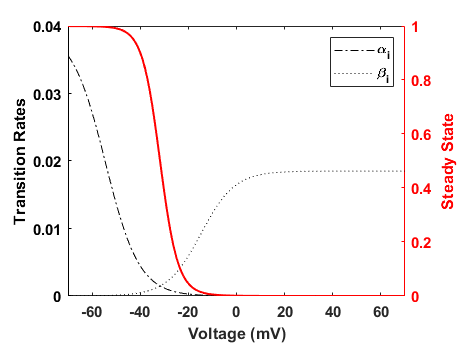


figure('Color','w')
yyaxis left
plot(volt,kto_kv(:,3), '-.', 'Color','black')
hold on
plot(volt,kto_kv(:,4), ':', 'Color','black')
hold off
xlabel('Voltage (mV)')
set(gca, 'XLimSpec','Tight')
set(get(gca,'YLabel'), 'String','Transition Rates')
set(gca, 'YColor','black')

yyaxis right
plot(volt,kto_kv(:,3)./(kto_kv(:,3)+kto_kv(:,4)), 'Color','red', 'LineWidth',1.5)
set(get(gca,'YLabel'), 'String','Steady State')
set(gca, 'YColor','red')
legend('\alpha_{i}','\beta_{i}','')
set(gca, 'FontWeight','bold', 'FontSize',11)

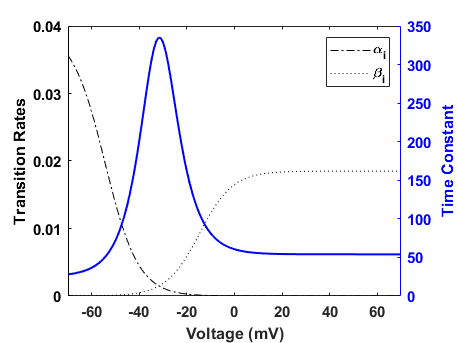


figure('Color','w')
yyaxis left
plot(volt,kto_kv(:,3), '-.', 'Color','black')
hold on
plot(volt,kto_kv(:,4), ':', 'Color','black')
hold off
xlabel('Voltage (mV)')
set(gca, 'XLimSpec','Tight')
set(get(gca,'YLabel'), 'String','Transition Rates')
set(gca, 'YColor','black')

yyaxis right
plot(volt,1./(kto_kv(:,3)+kto_kv(:,4)), 'Color','blue', 'LineWidth',1.5)
set(get(gca,'YLabel'), 'String','Time Constant')
set(gca, 'YColor','blue')
legend('\alpha_{i}', '\beta_{i}', '')
set(gca, 'FontWeight','bold', 'FontSize',11)

IKslow1

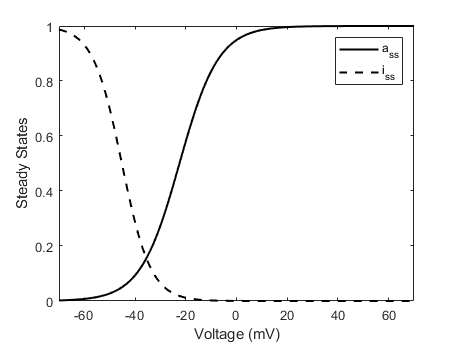

kslow1_kv = ikslow1_kinetic_var(kslow1_default,volt);

figure('Color','w')
plot(volt,kslow1_kv(:,1), 'Color','black', 'LineWidth',1.5)
hold on
plot(volt,kslow1_kv(:,2), '--', 'Color','black', 'LineWidth',1.5)
hold off
set(gca,'XLimSpec','Tight')
xlabel('Voltage (mV)')
ylabel('Steady States')
legend('a_{ss}','i_{ss}')

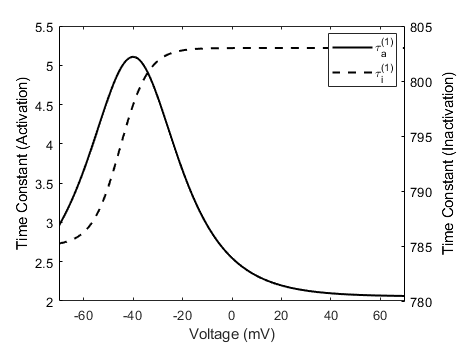

set(gca, 'FontWeight','bold', 'FontSize',11)

figure('Color','w')
yyaxis left
plot(volt,kslow1_kv(:,3), 'Color','black', 'LineWidth',1.5)
set(get(gca,'YLabel'), 'String','Time Constant (Activation)')
set(gca, 'YColor','black')
yyaxis right
plot(volt,kslow1_kv(:,4), '--', 'Color','black', 'LineWidth',1.5)
set(get(gca,'YLabel'), 'String','Time Constant (Inactivation)')
set(gca, 'YColor','black')
set(gca,'XLimSpec','Tight')
xlabel('Voltage (mV)')
legend('\tau_{a}^{(1)}','\tau_{i}^{(1)}', 'Location','best')

set(gca, 'FontWeight','bold', 'FontSize',11)

IKslow

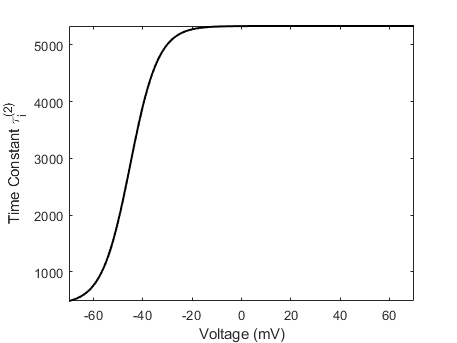

kslow2_kv = ikslow2_kinetic_var(kslow2_default,kslow1_kv(:,2));
figure('Color','w')
plot(volt, kslow2_kv, 'Color','black', 'LineWidth',1.5)
axis tight
xlabel('Voltage (mV)')
ylabel('Time Constant \tau_{i}^{(2)}')

set(gca, 'FontWeight','bold', 'FontSize',11)

IKss

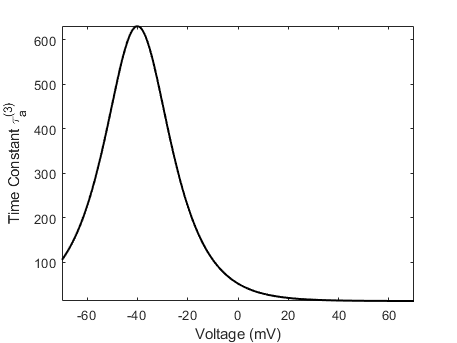

kss_kv = ikss_kinetic_var(kss_default,volt);

figure('Color','w')
plot(volt,kss_kv, 'Color','black', 'LineWidth',1.5)
axis tight
xlabel('Voltage (mV)')
ylabel('Time Constant \tau_{a}^{(3)}')

set(gca, 'FontWeight','bold', 'FontSize',11)

function kv = ikto_kinetic_var(p, V)
    kv = NaN(length(V),4);
    
    alpha1 = p(7).*exp(p(5).*(V+p(1)));
    beta1 = p(8).*exp(-p(6).*(V+p(1)));
    
    alpha2_temp1 = p(9).*exp((V+p(2))./(-1.0.*p(4)));
    alpha2_temp2 = p(10).*exp((V+p(2)+p(3))./(-1.0.*p(4)));
    alpha2 = alpha2_temp1./(1.0+alpha2_temp2);

    beta2_temp1 = p(11).*exp((V+p(2)+p(3))./p(4));
    beta2_temp2 = p(12).*exp((V+p(2)+p(3))./p(4));
    beta2 = beta2_temp1./(1.0+beta2_temp2);

    kv(:,1) = alpha1;
    kv(:,2) = beta1;
    kv(:,3) = alpha2;
    kv(:,4) = beta2;
end

function kv = ikslow1_kinetic_var(p, V)
    kv = NaN(length(V),4);
    kv(:,1) = 1.0./(1.0+exp(-(p(1)+V)./p(4))); % ass
    kv(:,2) = 1.0./(1.0+exp((p(2)+V)./p(5))); % iss
    kv(:,3) = p(7)./(exp(p(6)*(V+p(3))) + exp(-p(6)*(V+p(3))))+p(9); % taua
    kv(:,4) = p(10) - p(8)./(1.0+exp((p(2)+V)./p(5))); % taui
end

function kv = ikslow2_kinetic_var(p,iss)
    kv = p(2) - p(1).*iss; % taui
end

function kv = ikss_kinetic_var(p, V)
    kv = NaN(length(V),1);
    kv(:,1) = p(2)./(exp(p(1)*(V+p(4))) + exp(-p(1)*(V+p(4)))) + p(3);
end